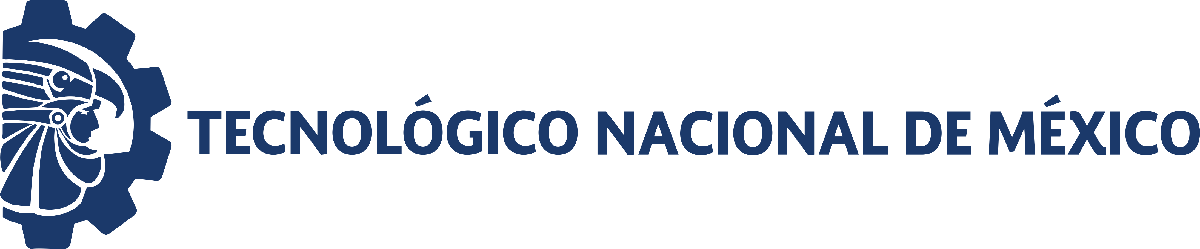                                 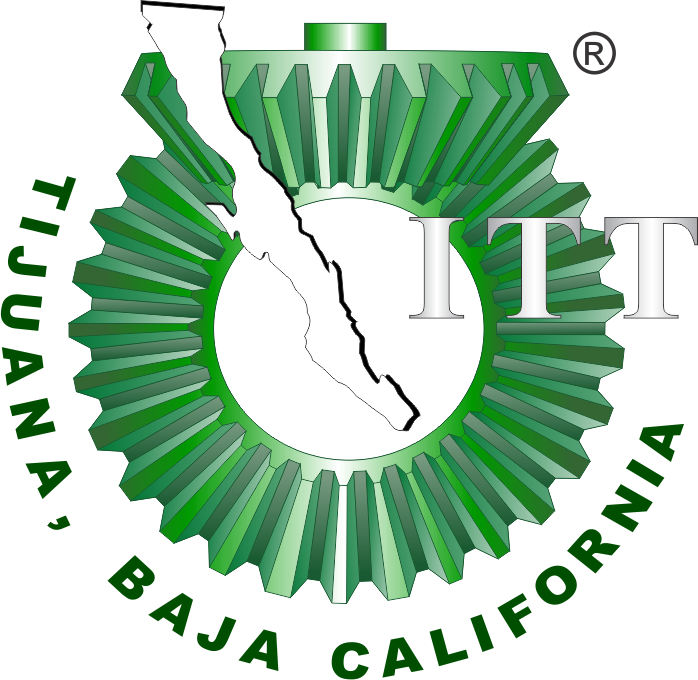

# Proyecto: Sistema Gastrointestinal

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general           

##          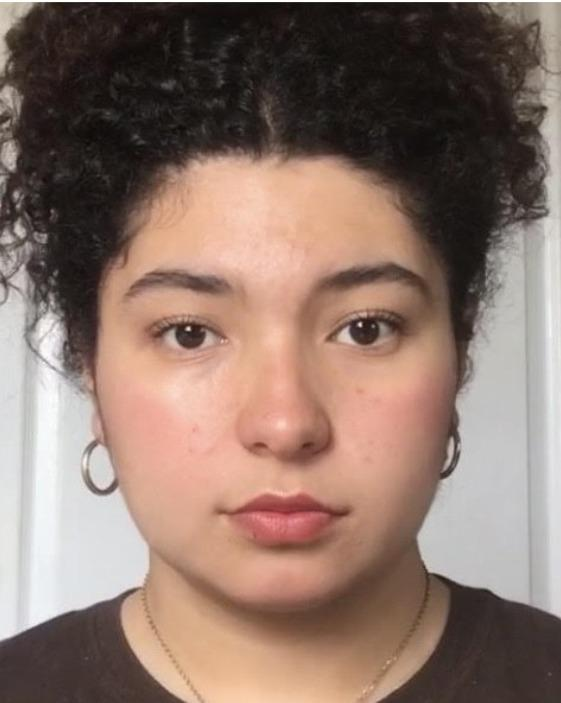 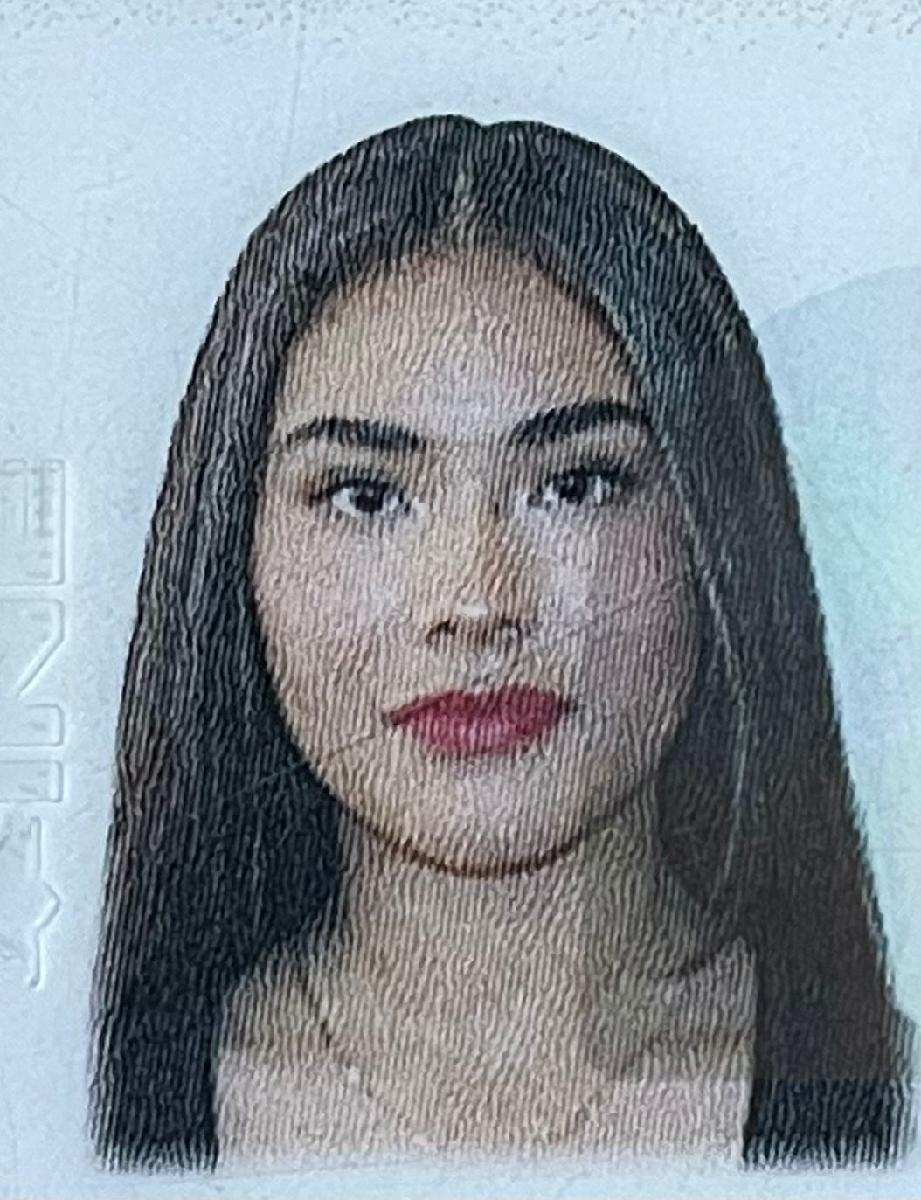 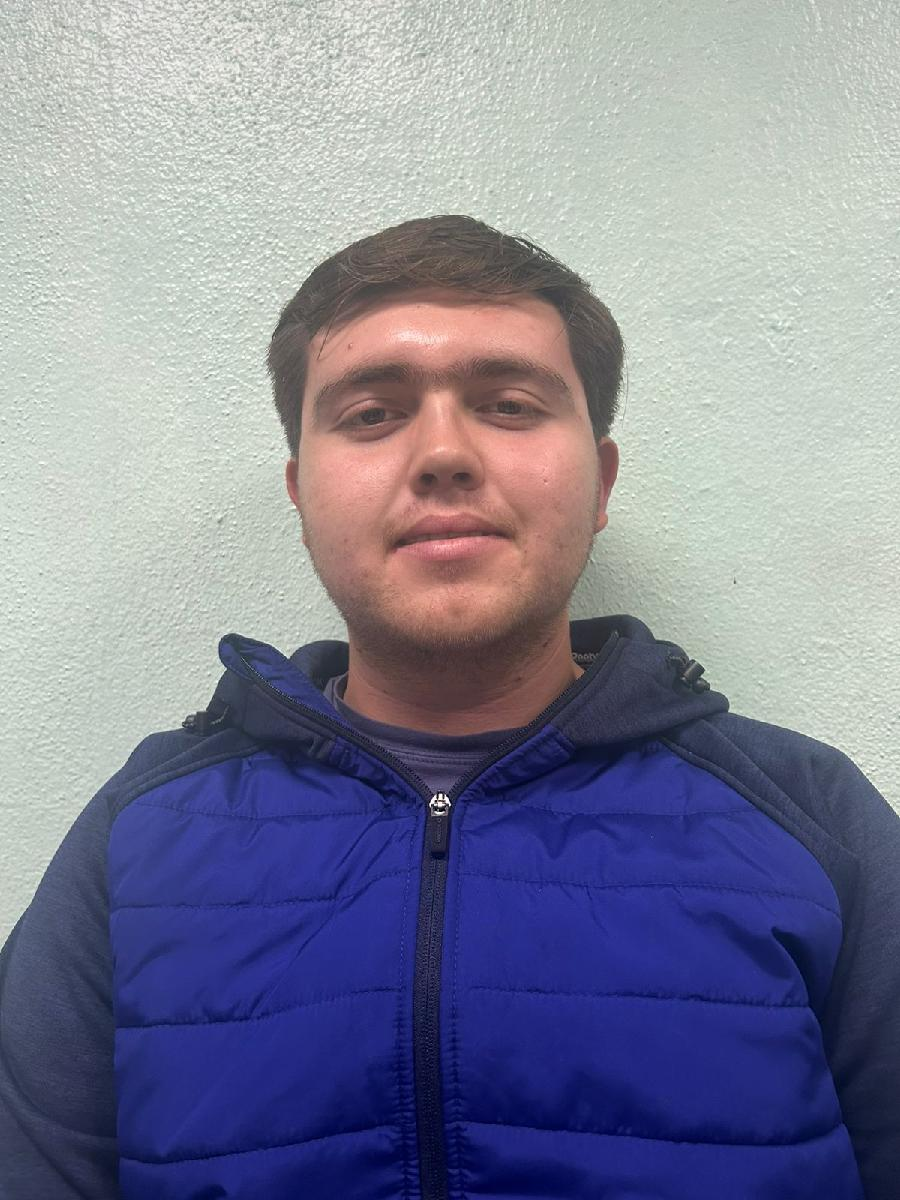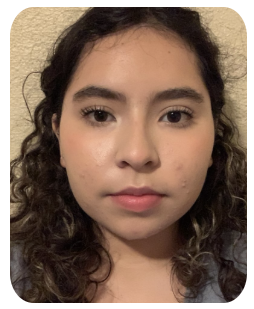

Nombre del alumno: DE LA TORRE GOMEZ JOHANA,GARCIA MURILLO KARLA VALERIA,LOPEZ LOPEZ SANTIAGO, URBINA GOMEZ ELIZA YASUNARI

Número de control: 22211751, 22212385, 22212260, 22211768

Correo institucional: **l22211751@tectijuana.edu.mx,  l22212385@tectijuana.edu.mx,l22212260@tectijuana.edu.mx, l22211768@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'gastrointestinal';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('gastrointestinal/Ve(t)','Amplitude','1');
set_param('gastrointestinal/Ve(t)','Bias','0');
set_param('gastrointestinal/Ve(t)','Frequency','1');
set_param('gastrointestinal/Ve(t)','Phase','0');
x1 = sim(file,parameters);
writematrix( x1.Vp,'Signal.xlsx')

## Lazo Abierto 

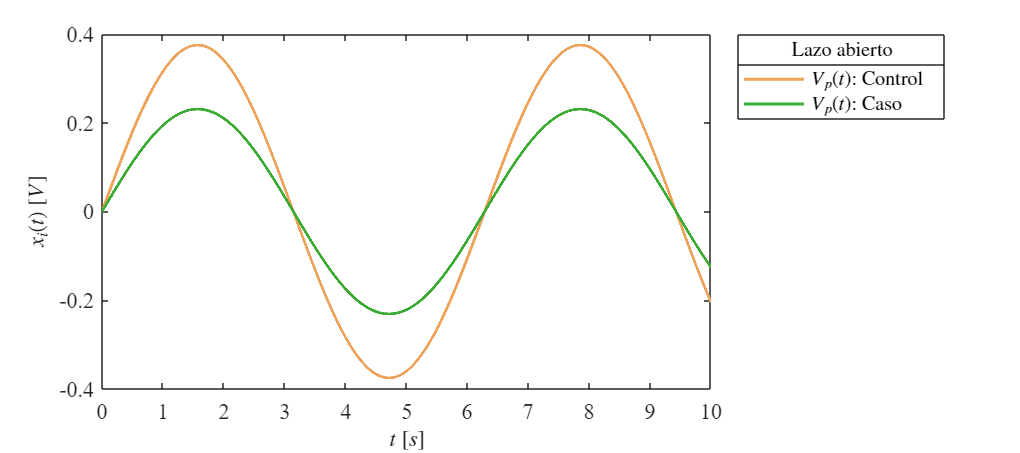

plotsignals(x1.t,x1.Vp2,x1.Vp4)

## Lazo Cerrado

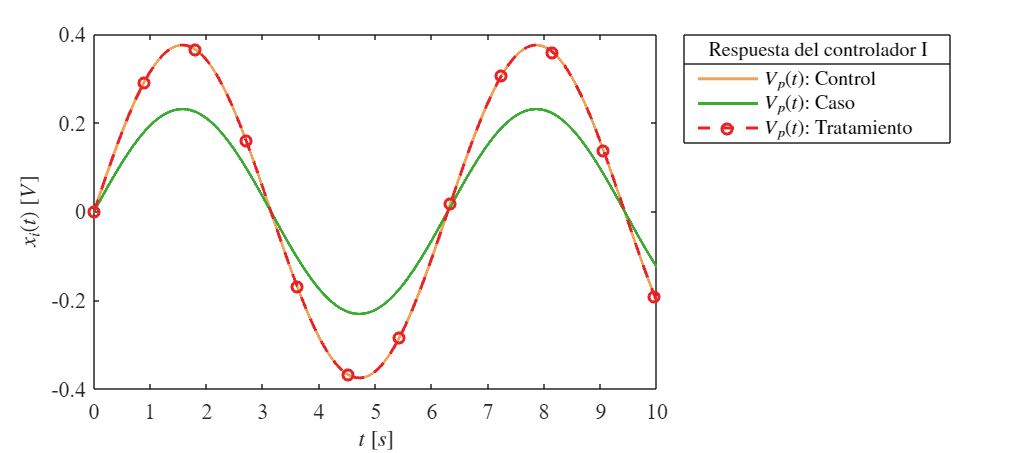

plotsignals2 (x1.t,x1.Vp2,x1.Vp4,x1.Vp5)

## Funcion: Respuesta a las señales

function plotsignals (t,Vp2,Vp4,Signal)
    set(figure(),'Color',"W")
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [0.93,0.64,0.35;   
                0.23,0.67,0.20;
                0.90,0.15,0.15;
                0.68,0.46,0.85;
                0.13,0.09,0.48;
                1.00,0.29,0.76];
    colororder(mycolors)

p = plot(t,Vp2,'-',t,Vp4,'-',...
    'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
set(p,'LineWidth',1.5)
L = legend('$V_p(t)$: Control','$ V_p(t)$: Caso');
set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
title(L,'Lazo abierto','FontSize',10)

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10);
    
    exportgraphics(gcf,['LazoAbierto.pdf'],'ContentType','vector')
    exportgraphics(gcf,['LazoAbierto.png'],'ContentType','vector')
end

function plotsignals2 (t,Vp2,Vp4,Vp5,Signal)
    set(figure(),'Color',"W")
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [0.93,0.64,0.35;   
                0.23,0.67,0.20;
                0.90,0.15,0.15;
                0.68,0.46,0.85;
                0.13,0.09,0.48;
                1.00,0.29,0.76];
    colororder(mycolors)

p = plot(t,Vp2,'-',t,Vp4,'-',t,Vp5,'--o',...
    'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
set(p,'LineWidth',1.5)
L = legend('$V_p(t)$: Control','$V_p(t)$: Caso','$V_p(t)$: Tratamiento');
set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
title(L,['Respuesta del controlador I'],'FontSize',10)

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10);
    
    exportgraphics(gcf,['Respuesta.pdf'],'ContentType','vector')
    exportgraphics(gcf,['Respuesta.png'],'ContentType','vector')
end
